# Dynamic Modeling of a Two-wheeled Inverted Pendulum Balancing Mobile Robot 

https:core.ac.uk/download/pdf/287648002.pdf


$$W_1 =2\left(-\frac{n^2 J_{\textrm{eq}} +J_b }{r^2 }-M_w \right)-M_b +\;\frac{M_b^2 L^2 }{J_b +M_b L^2 }$$


 [https://journals.sagepub.com/doi/pdf/10.5772/63933](https://journals.sagepub.com/doi/pdf/10.5772/63933)


$$\left\lbrack \begin{array}{c}
{\dot{x} }_b \\
{\ddot{x} }_b \\
\dot{\theta} \\
\ddot{\theta} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & \frac{2n^2 K_e K_t }{r^2 R_a \cdot W_1 } & -\frac{M_b^2 L^2 g\;}{W_1 \left(J_b -M_b L^2 \right)} & 0\\
0 & 0 & 0 & 1\\
0 & \frac{2n^2 K_e K_t }{r^2 R_a \cdot W_1 \left(\frac{J_b }{M_b L}+L\right)} & \frac{{-M}_b^2 L^2 g}{W_1 \left(\frac{J_b }{M_b L}+L\right)\left(\left(J_b {\;+\;M}_b L^2 \right)+{g\;W}_1 \right)} & 0
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x_b \\
{\dot{x} }_b \\
\theta \\
\dot{\theta} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
-\frac{2{n\;K}_t }{r\;R_a W_1 }\\
0\\
-\frac{2n\;K_t }{r\;R_a W_1 \left(\frac{J_b }{M_b L}+L\right)}
\end{array}\right\rbrack \cdot V_a$$


%https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=6565146


clear

% DC Motor Praters 
IStall = 2;
TStall = 0.15;
Inoload = 0.2;



n = 20;
g = 9.8067;
dt = 0.002; 

Kt = ((IStall - Inoload)/ TStall) ^-1

Kt = 0.0833

Ke = (0.6594*20*n*2*pi)^-1

Ke = 6.0341e-04

Ra = 2;
r = 0.04; 
L = 0.085;
D = 0.132;

Mb = 0.8;
Mw = 0.025;

Jeq = 0.0003;
Jw = 0.5*Mw*2*r^2

Jw = 4.0000e-05

Jb = (L^2+D^2) * Mb/12 

Jb = 0.0016

W1 = 2*((-n*n*Jeq +Jw)/(r^2 )- Mw)- Mb + (Mb*Mb*L*L)/(Jb+Mb*L*L)

W1 = -150.1771

W2 = W1*((L+Jb)/(Mb*L));

A11 = (2*n*n*Ke*Kt)/(r*r*Ra*W1);
A13 = (2*n*n*Ke*Kt)/(r*r*Ra*W2);
A21 = -(Mb*Mb*L*L*g)/(W1*(Jb+Mb*L*L));
A23 = -(Mb*Mb*L*L*g)/(W2*((Jb+Mb*L*L)+g*W1));

B1 = (-2*n*Kt)/(r*Ra*W1);
B3 = (-2*n*Kt)/(r*Ra*W2);
 

A = [0 1 0 0; 0 A11 A21 0;0 0 0 1; 0 A13 A23 0 ]

A =          0    1.0000         0         0
         0   -0.0837    0.0407         0
         0         0         0    1.0000
         0   -0.0657   -0.0000         0


B = [0; B1; 0; B3];
C = [1 0 0 0; 0 0 1 0];
D = eye(2,0);

P = ss(A,B,C,D)


P =
 
  A = 
               x1          x2          x3          x4
   x1           0           1           0           0
   x2           0    -0.08371     0.04068           0
   x3           0           0           0           1
   x4           0     -0.0657  -1.609e-07           0
 
  B = 
           u1
   x1       0
   x2  0.2775
   x3       0
   x4  0.2178
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


rank(obsv(A,C))

ans = 4

rank(ctrb(A,B))

ans = 4

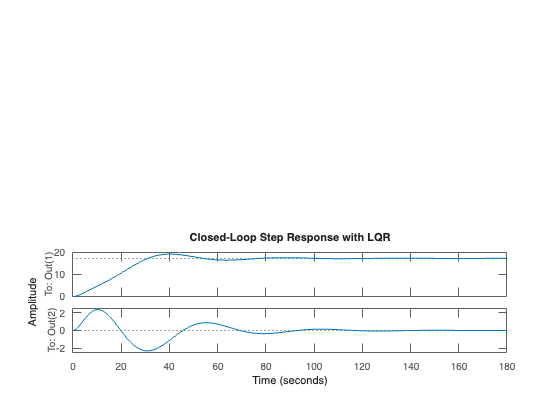


% LQR Design
Q = diag([1 0.01 0.01 4]); % State cost weights
R = 300;            % Control effort weight

% Compute Discrete-Time LQR Gain
Ts = 5E-3;          % Sampling Time (10 ms)
K = lqrd(A, B, Q, R, Ts);

% Closed-Loop System
Ac = A -B*K;        % Closed-loop system matrix
sys_cl = ss(Ac, B, C, D); % Continuous closed-loop system

% Discretize the Closed-Loop System
dP = c2d(sys_cl, Ts, 'ZOH'); % Zero-Order Hold discretization

% Open-Loop and Closed-Loop Response
G = ss(A, B, C, D);   % Open-loop system
G_cl = ss(Ac, B, C, D); % Closed-loop system

% Step Response Comparison
figure;
subplot(2,1,2);
step(G_cl); title('Closed-Loop Step Response with LQR');

disp(K);

    0.0577    0.5826    0.2436    0.6264



## State Space Control

deg2rad(102)

ans = 1.7802